# Matlab live script for analyzing 2 chamber auditory conditioned place avoidance task

You will need the following files/data:

- CSV file created by the DLC (centre x and centre y tracking only)

- Bonsai XY file created by Bonsai during testing.

- Video file used in the DLC.

## Import DLC data

clear all;close all;clc;

% import raw DLC data as a table
[fileName, pathName] = uigetfile('*.csv');

opts = delimitedTextImportOptions("NumVariables", 13);

% Specify range and delimiter
opts.DataLines = [4, Inf];
opts.Delimiter = ",";

% Specify column names and types
%opts.VariableNames = ["scorer","centre_x", "centre_y", "centre_accuracy", "tail_x", "tail_y", "tail_accuracy", "shelter_x", "shelter_y", "shelter_accuracy"];
%opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

opts.VariableNames = ["scorer","centre_x", "centre_y", "centre_accuracy"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
DLCraw = readtable(fullfile(pathName,fileName),opts);
clear opts

## Import Bonsai XY

% import bonsai xy data as a table
[fileName, pathName] = uigetfile('*.csv');

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [4, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["timestampmiliseconds"];
opts.VariableTypes = ["double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
BonsaiXY = readtable(fullfile(pathName,fileName),opts);
clear opts

BonsaiXY.timestamp = (BonsaiXY.timestampmiliseconds(:,1)-BonsaiXY.timestampmiliseconds(1,1))/1000;

### Equalize the Number of Rows from BonsaiXY and DLCraw to combine both files

% Equalize the row numbers.
Min = min([height(BonsaiXY),height(DLCraw)]);
BonsaiXY = BonsaiXY(1:Min,:);DLCraw = DLCraw(1:Min,:);

DLCraw.timestamp = BonsaiXY.timestamp;

DLCraw = movevars(DLCraw, 'timestamp', "Before", 'scorer');

### Fill in missing low accuracy DLC data

acc_threshold = 0.8;

error_centreIDX = find(DLCraw.centre_accuracy < acc_threshold);
DLCraw.centre_x(error_centreIDX) = NaN;
DLCraw.centre_y(error_centreIDX) = NaN;
DLCraw.centre_x = fillmissing(DLCraw.centre_x,"nearest");
DLCraw.centre_y = fillmissing(DLCraw.centre_y,"nearest");

## Create a timetable with new features.

DLCdata = table(DLCraw.centre_x, DLCraw.centre_y,'VariableNames', {'centre_x', 'centre_y'});
DLCdata.Time = DLCraw.timestamp;

centre = [DLCdata.centre_x DLCdata.centre_y];

clear x y;
v_centre = [];
v_centre(1) = 0;
x = centre(:,1);
y = centre(:,2);
for ii = 2:length(centre)
    v_centre(ii) = pdist([x(ii-1) y(ii-1); x(ii) y(ii)], 'euclidean');
end
v_centre = v_centre';

DLCdata.v_centre = v_centre;

fps = 1/mean(diff(DLCdata.Time));
DLCdata.fps(:) = fps;

DLCdata

DLCdata = 37235×5 table
    centre_x    centre_y      Time      v_centre     fps  
    ________    ________    ________    ________    ______

     631.27      200.17            0          0     29.798
     631.14       199.7     0.023104    0.48084     29.798
     631.18      199.55      0.05792    0.15735     29.798
     631.97       199.3     0.086413    0.82385     29.798
     632.25       198.3      0.15201     1.0371     29.798
     632.45      197.82      0.17352    0.52509     29.798
     632.68      196.22      0.19917     1.6077     29.798
     633.53      195.25      0.23195     1.2964     29.798
     634.25      193.98      0.26399      1.457     29.798
     633.75      193.73      0.29609    0.56338     29.798
     633.92      191.92      0.32847     1.8194     29.798
        634      191.65       0.3594  

## Create event to analyze length of data for habituation or test session

Habituation consisted of 10 min worth of data whereas, test consisted of 15 min worth of data.

**!!!Comment out the block you are not analyzing!!!**

### Habituation: Create event to analyze 10 min worth of data:

Selecting 10 min worth of data for analysis corresponding to frames from 10 sec to 10 min 10 sec.

event_X = {};

[~,startrow] = (min(abs(DLCdata.Time - 10)));
[~,endrow] = (min(abs(DLCdata.Time - 610)));
event_X = DLCdata(startrow:endrow,:);

durationevent_X = event_X.Time(end)-event_X.Time(1)

durationevent_X = 600.0415

event_X

event_X = 17856×5 table
    centre_x    centre_y     Time     v_centre     fps  
    ________    ________    ______    ________    ______

     623.37      143.75     9.9771    0.93269     29.798
     621.82      143.36     10.026     1.6003     29.798
      622.2      143.22     10.058    0.40654     29.798
     620.52      142.57      10.09     1.8031     29.798
     619.85      142.03     10.122    0.85931     29.798
     619.78      141.51     10.159    0.52527     29.798
     619.65      141.68      10.19    0.20813     29.798
     620.14      141.94      10.23    0.54913     29.798
     620.68      141.98     10.258    0.54073     29.798
     620.37      141.43     10.287     0.6338     29.798
     621.81      140.59     10.317     1.6697     29.798
     621.39      139.77     10.356    0.92735     29.798
     62

### Test: Create event to analyze 15 min worth of data:

Selecting 15 min worth of data for analysis corresponding to frames from 10 sec to 10 min 10 sec.

event_X = {};

[~,startrow] = (min(abs(DLCdata.Time - 10)));
[~,endrow] = (min(abs(DLCdata.Time - 910)));
event_X = DLCdata(startrow:endrow,:);

durationevent_X = event_X.Time(end)-event_X.Time(1)

durationevent_X = 900.0146

event_X

event_X = 26806×5 table
    centre_x    centre_y     Time     v_centre     fps  
    ________    ________    ______    ________    ______

     623.37      143.75     9.9771    0.93269     29.798
     621.82      143.36     10.026     1.6003     29.798
      622.2      143.22     10.058    0.40654     29.798
     620.52      142.57      10.09     1.8031     29.798
     619.85      142.03     10.122    0.85931     29.798
     619.78      141.51     10.159    0.52527     29.798
     619.65      141.68      10.19    0.20813     29.798
     620.14      141.94      10.23    0.54913     29.798
     620.68      141.98     10.258    0.54073     29.798
     620.37      141.43     10.287     0.6338     29.798
     621.81      140.59     10.317     1.6697     29.798
     621.39      139.77     10.356    0.92735     29.798
     62

## Define the 2 chamber apparatus boundaries

% Choose the movie file you used in DLC
[MfileName, MpathName] = uigetfile('*.*');
v = VideoReader(fullfile(MpathName,MfileName));

Define boundaries of the chamber apparatus

frame = read(v,900); %frame will be used to define the apparatus
imshow(frame);
ROI_apparatus = drawrectangle('LineWidth',0.5,'StripeColor','blue','Label','Apparatus Zone');
inapparatus =inROI(ROI_apparatus, event_X.centre_x(1:end), event_X.centre_y(1:end));
close

Define width of the apparatus

imshow(frame);
ROI = drawpolygon('LineWidth',0.5,'StripeColor','cyan','Label','Cage width');
cage_width = ROI.Position(1, 2)-ROI.Position(1,1);
close

Lpoints =   159.3837  102.3605
  159.3837  470.7326
  399.3837  470.7326
  399.3837  102.3605


Rpoints =   424.5000   99.5698
  424.5000  470.7326
  664.5000  470.7326
  664.5000   99.5698


## Correct centre x and centre y data 

### Remove and replace centre_x and centre_y points outside of the apparatus

error = find(inapparatus < 1);
    event_X.centre_x(error) = NaN;
    event_X.centre_y(error) = NaN;

event_X.centre_x = fillmissing(event_X.centre_x,'linear');
event_X.centre_y = fillmissing(event_X.centre_y,'linear');

### Remove and replace outliers for centre_x and centre_y points

centre_x

% fill missing datapoints
    missingcentre_x = fillmissing(event_X.centre_x,'linear');
    event_X.centre_x = missingcentre_x;

% compile corrected DLC tracking data
centre_xcorrected = [];
    centre_xcorrected = filloutliers(event_X.centre_x,'linear', "movmedian" ,[2 2]);
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.

centre_y

% fill missing datapoints
    missingcentre_y = fillmissing(event_X.centre_y,'linear');
    event_X.centre_y = missingcentre_y;

centre_ycorrected = [];

    centre_ycorrected = filloutliers(event_X.centre_y,'linear', "movmedian" ,[2 2]);
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.

### Plot corrected centre_x and centre_y data

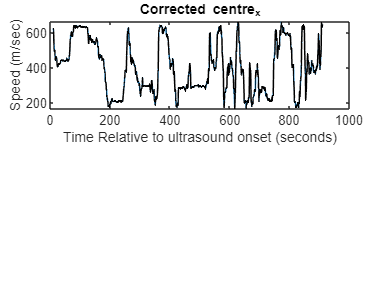

ERF_time = event_X.Time(1:end);
    
figure
subplot(2,1,1)
plot(ERF_time,centre_xcorrected)
title ('Corrected centre_x')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Speed (m/sec)')
hold on
plot(ERF_time,mean(centre_xcorrected,2),'k','LineWidth',1)

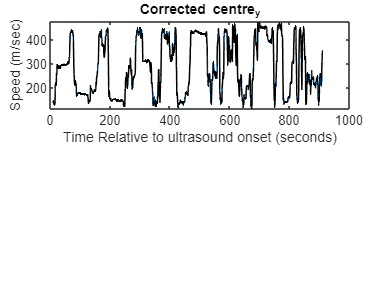


figure
subplot(2,1,1)
plot(ERF_time,centre_ycorrected)
title ('Corrected centre_y')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Speed (m/sec)')
hold on
plot(ERF_time,mean(centre_ycorrected,2),'k','LineWidth',1)

% Update event variable with corrected position data
event_X.centre_x = centre_xcorrected;
event_X.centre_y = centre_ycorrected;

## Create variable for speed of centre point based on corrected centre x and centre y

centre = [event_X.centre_x event_X.centre_y];

clear x y;
v_centre = [];
v_centre(1) = 0;
x = centre(:,1);
y = centre(:,2);
for ii = 2:length(centre)
    v_centre(ii) = pdist([x(ii-1) y(ii-1); x(ii) y(ii)], 'euclidean');
end
v_centre = v_centre';

event_X.v_centre = v_centre;

### Remove and replace outliers for speed

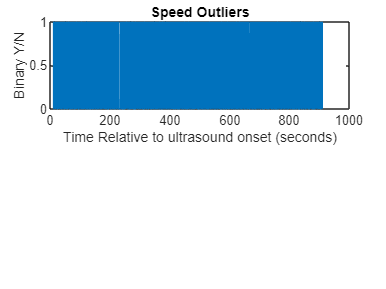

% Fill missing datapoints
missingspeed = fillmissing(event_X.v_centre,'linear');
event_X.v_centre = missingspeed;

% Identify speed outliers
speedoutliers = [];
speedoutliers = isoutlier(event_X.v_centre,"movmedian",[50 50]);

ERF_time = event_X.Time(1:end);
figure
subplot(2,1,1)
plot(ERF_time,speedoutliers)
title ('Speed Outliers')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Binary Y/N')

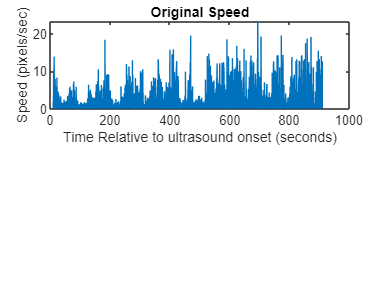


% Compile original DLC tracking data
% Here we are dividing by pixelsperm to get speed in m/s instead of pixels/s
originalspeed =[];
originalspeed = event_X.v_centre;

figure
subplot(2,1,1)
plot(ERF_time,originalspeed)
title ('Original Speed')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Speed (pixels/sec)')

### Plot corrected speed data

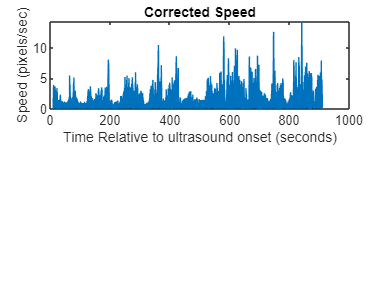

% Compile corrected DLC tracking data
speedcorrected = [];
speedcorrected = filloutliers(event_X.v_centre,'linear', "movmedian" ,[50 50]);
% Speed is divided by pixelsperm to convert from pixels/sec to m/sec
% "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
% "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
% This method is also known as a Hampel filter.

figure
subplot(2,1,1)
plot(ERF_time,speedcorrected)
title ('Corrected Speed')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Speed (pixels/sec)')

### Convert speed data from pixels/sec to meters/sec

% Determine how many pixels per m in the video
% The width of the apparatus in m is 0.2.
% Dividing the width in pixels by the shelter radius in meters will give you the number of pixels per meter.
pixelsperm = (abs(cage_width))/0.2;
speedmeterspersec = speedcorrected/pixelsperm;
distance_travelled_meters = sum(speedmeterspersec); % total distance travelled in meters

## Compute the time spent in each chamber

### Define left and right chambers

imshow(frame);
leftchamber = drawrectangle('LineWidth',0.5,'StripeColor','Red','Label','Left Chamber');
rightchamber = drawrectangle('LineWidth',0.5,'StripeColor','Blue','Label','Right Chamber');

Lpoints = leftchamber.Vertices;
Rpoints = rightchamber.Vertices;

### Compute the time spent inside the left and right chambers

insideleftchamber = inROI(leftchamber,event_X.centre_x(1:end), event_X.centre_y(1:end));
leftchamber_totalrows = sum(insideleftchamber);

insiderightchamber = inROI(rightchamber,event_X.centre_x(1:end), event_X.centre_y(1:end));
rigthchamber_totalrows = sum(insiderightchamber);

close

rowsinevent_X = size(event_X,1);
durationevent_X = event_X.Time(end)-event_X.Time(1);
timeperrow = (event_X.Time(end)-event_X.Time(1))/rowsinevent_X;

timeleftchamber = timeperrow*leftchamber_totalrows;
timerightchamber = timeperrow*rigthchamber_totalrows;

timeinpreferredchamber = [];
if timeleftchamber>timerightchamber;
    timeinpreferredchamber = timeleftchamber;
    timeinotherchamber = timerightchamber;
elseif timeleftchamber<timerightchamber;
    timeinpreferredchamber = timerightchamber;
    timeinotherchamber = timeleftchamber;
end


## Create event to analyze length of data for habituation or test session

The preference index is simply looking at baseline preference for one of the chambers when the ultrasound is not paired with either chamber. 

The real time place aversion index is looking at how animals avoid the ultrasound paired chamber (assigned to the baseline preferred chamber identified during habituation)

**!!!Comment out the block you are not analyzing!!!**

### Habituation: Calculate the chamber preference index during habituation (no ultrasound pairing)

preferenceindex = (timeleftchamber-timerightchamber)/(timeleftchamber+timerightchamber);

### Test: Calculate the real time place aversion index during test (ultrasound pairing)

RTPAindex = (timeinpreferredchamber-timeinotherchamber)/(timeinpreferredchamber+timeinotherchamber);

## Compile parameters

compileddata = [];
compileddata.timeinpreferredchamber = timeinpreferredchamber;
compileddata.timeinotherchamber = timeinotherchamber;
compileddata.preferenceindex = preferenceindex;
compileddata.RTPAindex = RTPAindex;
compileddata.distance_travelled_meters = distance_travelled_meters;

compileddata

compileddata = struct with fields:
       timeinpreferredchamber: 467.3992
           timeinotherchamber: 394.3733
              preferenceindex: 0.0847
                    RTPAindex: 0.0847
    distance_travelled_meters: 104.9726


## Plot locomotion trajectory in 2 chamber apparatus

Left chamber verticies

p1 = [Lpoints(1,1) Lpoints(1,2)];
p2 = [Lpoints(2,1) Lpoints(2,2)];
p3 = [Lpoints(3,1) Lpoints(3,2)];
p4 = [Lpoints(4,1) Lpoints(4,2)];

Right chamber verticies

p5 = [Rpoints(1,1) Rpoints(1,2)];
p6 = [Rpoints(2,1) Rpoints(2,2)];
p7 = [Rpoints(3,1) Rpoints(3,2)];
p8 = [Rpoints(4,1) Rpoints(4,2)];

Create figure with chambers and locomotion trajectory

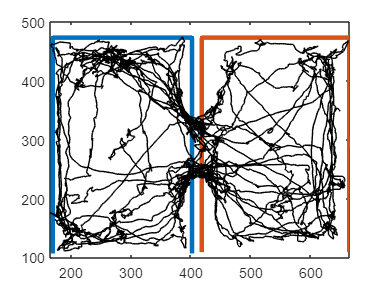

figure
plot([p1(1) p2(1) p3(1) p4(1)], [p1(2) p2(2) p3(2) p4(2)], 'Linewidth', 3)
hold on
plot([p5(1) p6(1) p7(1) p8(1)], [p5(2) p6(2) p7(2) p8(2)], 'Linewidth', 3)
hold on
plot(centre_xcorrected, centre_ycorrected, 'k')

## Save the entire workspace as a mat file

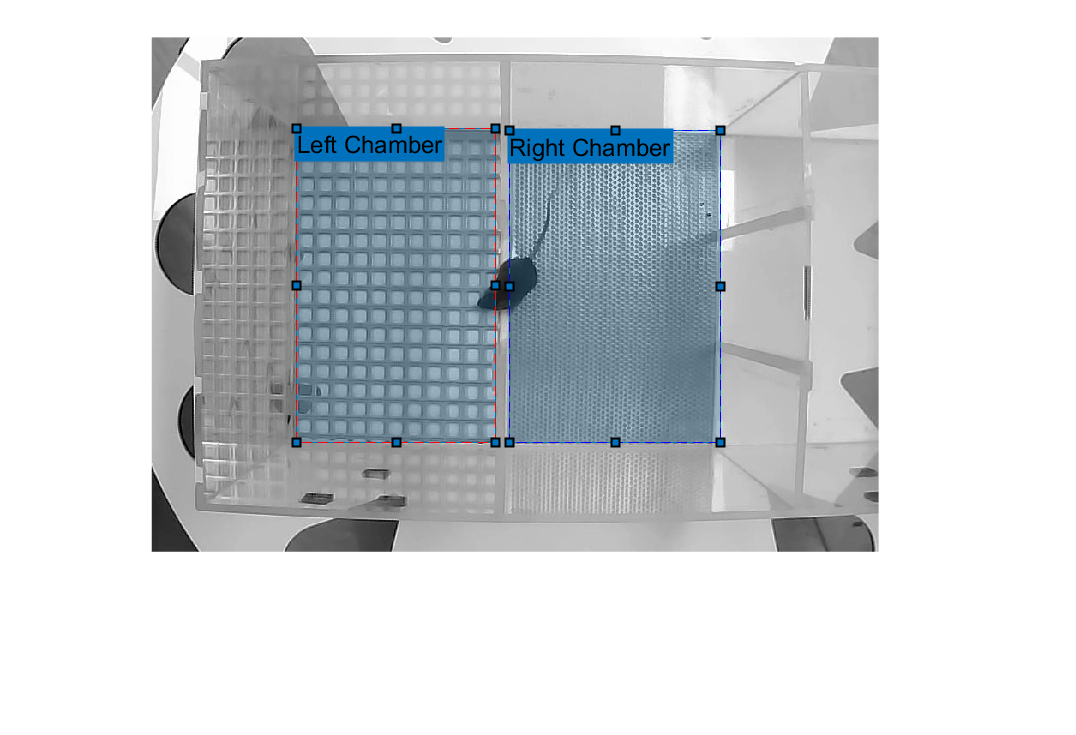

uisave